# Augmented Reality Matlab Capstone Project (Demo Version)

## Access All Relevant File Paths

%--- Add paths to files---
addpath("All Functions/Control Functions/")
addpath("All Functions/CORF Functions/")
addpath("All Functions/doors/")
addpath("All Functions/windows/")
addpath("All Functions/LSD Rafael Matlab/")
addpath("All Functions/Functions For Augmenting Workflow")

## Load Video Frame or Reference Picture

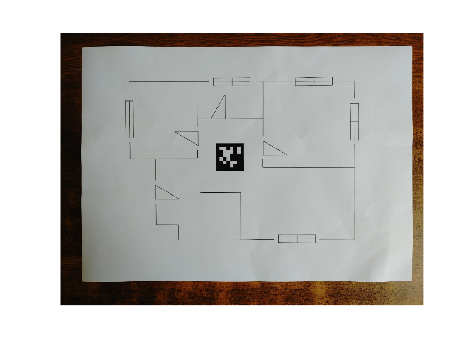

file_num = input('***Sample Reference Images***\n1. test_sample_floor_plan1\n2. test_sample_floor_plan2\nSelect a reference image (Enter a number 1 or 2): ');
while isempty(file_num) || ~isnumeric(file_num) || ~ismember(file_num, [1, 2])
    warning('Invalid input. Enter number 1 or 2.');
    file_num = input('Enter number 1 or 2: ');
end

image_path = "Test Pics/" + "test_sample_floor_plan" + file_num + ".jpeg";
img = imread(image_path);
if isempty(img)
    error("Image not found or unreadable.");
end
imshow(img);

img_ref = img;

## Get Camera Intrinsics

%load('calibrationSession.mat');
data = load('Demo_calibrationSession.mat');
session = data.calibrationSession;
cameraParams = session.CameraParameters;
intrinsics = cameraParams.Intrinsics;
disp(['Warning (not an error message): The calibrationSession file used here is for demonstration purposes only. ' ...
'Calibrate your camera and generate your own callibrationSession.mat file when running AR_runtime_file'])

Warning (not an error message): The calibrationSession file used here is for demonstration purposes only. Calibrate your camera and generate your own callibrationSession.mat file when running AR_runtime_file


## Estimate Pose

tagSize = 25; % in mm

tagFamily = "tag36h11";
[~, ~, tagPose] = readAprilTag(img, tagFamily, intrinsics, tagSize);

## Display the Axis

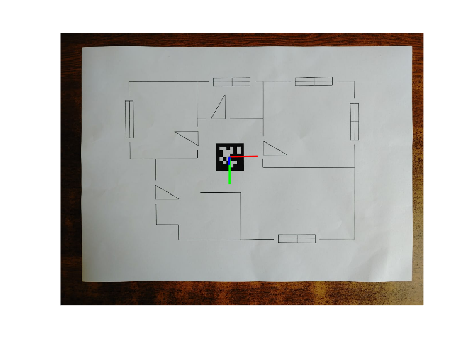

annotatedImage = helperInsertXYZAxes(img, tagPose, intrinsics, tagSize);
figure
imshow(annotatedImage)

## Rotate The Axis

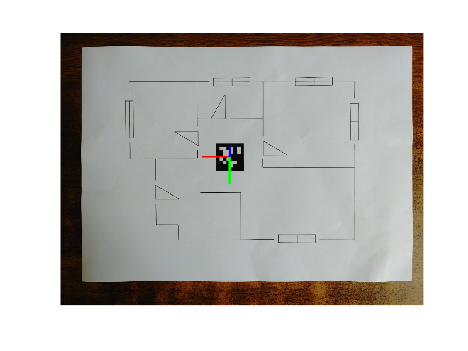

rotationAngles = [0 180 0];
tform = rigidtform3d(rotationAngles, [0 0 0]);
updatedR = tagPose.R * tform.R;
tagPose = rigidtform3d(updatedR, tagPose.Translation);


annotatedImage = helperInsertXYZAxes(img, tagPose, intrinsics, tagSize);
figure
imshow(annotatedImage)

## Document Detection Part 1

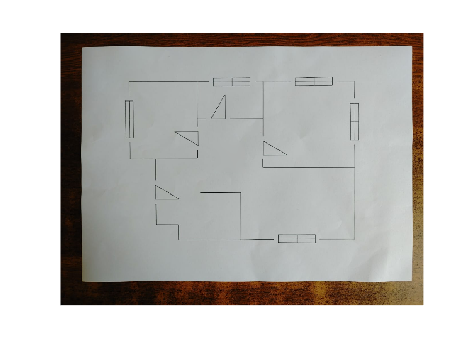

%--- This work flow aims to remove the surrounding background ---%
% --- Step1: Mask Out April Tag ---%
[cubeWidth, cubeHeight, ~] = deal(tagSize);

vertices = [ cubeWidth/2 -cubeHeight/2 0; 
             cubeWidth/2  cubeHeight/2 0;
            -cubeWidth/2  cubeHeight/2 0;
            -cubeWidth/2 -cubeHeight/2 0]; % World coordinates of april tag

projectedVertices = world2img(vertices, tagPose, intrinsics); % Image coordinates of april tagminX = min(projectedVertices(:,1));

minX = min(projectedVertices(:,1));
maxX = max(projectedVertices(:,1));
minY = min(projectedVertices(:,2));
maxY = max(projectedVertices(:,2));

bbox = [minX, minY, maxX-minX, maxY-minY];  % [x, y, width, height]

maskedImage = img;  % Initialize maskedImage with the original
% Scale bbox by 10 percent
scale = 0.1;
scaled_bbox = bboxScaler(bbox, scale);
% Begin masking the april tag
box = round(scaled_bbox);  % [x y w h]
x1 = max(1, box(1));
y1 = max(1, box(2));
x2 = min(size(img,2), x1 + box(3) - 1);
y2 = min(size(img,1), y1 + box(4) - 1);

% Create mask for region
mask = false(size(img,1), size(img,2));
mask(y1:y2, x1:x2) = true;

% Region fill (works on grayscale or per channel)
if size(img, 3) == 3
     for c = 1:3
         channel = uint8(maskedImage(:,:,c));
         filled = regionfill(channel, mask);
         maskedImage(:,:,c) = filled;
     end
else
    maskedImage = regionfill(maskedImage, mask);
end
imshow(maskedImage)

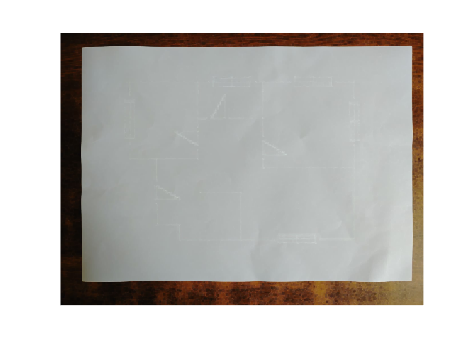



%--- Step 2: Erase all contents of the paper via Erosion ---%
% Define a 5x5 square structuring element
se = strel('square', 5);

% Apply closing operation 3 times
J = maskedImage;
for k = 1:3
    J = imclose(J, se);
end
imshow(J)

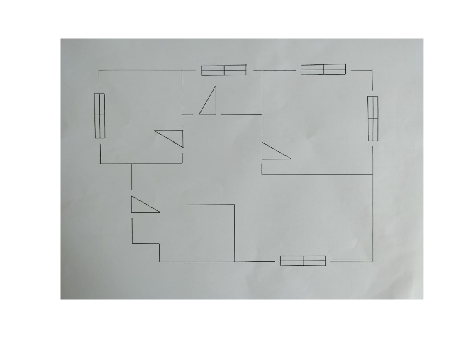


%--- Step 3: Run Square Detection Fxn to get bbox of  A4 paper ---%
% --- Convert to grayscale ---
if ndims(J) == 3
    gray = rgb2gray(J);
else
    gray = J;
end

gray = im2double(gray);

% --- smoothing ---
gray = imgaussfilt(gray, 1.0);   % sigma ≈ 1 for mild smoothing

% --- Apply CORF contour detector ---
sigma = 2.5;     % CORF scale 
t = 0.3;         % hysteresis high threshold 

[~, bin] = CORF(gray, sigma, t); % bin is a binary contour image

% Fill the thick-lined square to make it solid
bin_filled = imfill(bin, 'holes');

% Clean up with morphological closing
bin_filled = imclose(bin_filled, strel('disk', 3));

% get boundaries - 1 boundary per shape
[~, L] = bwboundaries(bin_filled, 'noholes');

properties = regionprops(L, 'BoundingBox', 'Area');
% Get region with the largest Area
[~, largestIdx] = max([properties.Area]);
A4Paper = properties(largestIdx).BoundingBox;


if isempty(A4Paper)
    % Give a default value if detection of A4 paper fails
    A4Paper = [60 49 1462 1032];
end


%--- Step 4: Crop the Original Image Without April Tag 'maskedImage' ---%
scale = -0.1; 
if ~isempty(A4Paper)
    % Get the smallest valid square
    [~, idx] = min(A4Paper(:, 3) .* A4Paper(:, 4));
    cropBox = A4Paper(idx, 1:4); % [x, y, width, height]
    % Scale crop box
    x = max(cropBox(1,1) - scale * cropBox(1,3) / 2, 0);
    y = max(cropBox(1,2) - scale * cropBox(1,4) / 2, 0);
    w = cropBox(1,3) * (1 + scale);
    h = cropBox(1,4) * (1 + scale);
    cropBox = [x, y, w, h];

    
    % Crop the image
    NoBackgroundImage = imcrop(maskedImage, cropBox);
    figure;
    imshow(NoBackgroundImage);
end

## Contour Detection Using CORF (1st Time Used on Floor Plan Proper)

% --- Convert to grayscale ---

if ndims(NoBackgroundImage) == 3
    gray = rgb2gray(NoBackgroundImage);
else
    gray = NoBackgroundImage;
end

gray = im2double(gray);

% --- smoothing ---
gray = imgaussfilt(gray, 1.0);   % sigma ≈ 1 for mild smoothing

% --- Apply CORF contour detector ---

[img_height, img_width] = size(gray);
img_diagonal = sqrt(img_height^2 + img_width^2);

% Scale sigma based on image size
% For close-up: sigma = 2.5 works
% For full page: sigma should be proportionally smaller
base_diagonal = 1000;  % Adjust based on your close-up image size
sigma = 2.5 * (base_diagonal / img_diagonal);
sigma = max(1.0, min(sigma, 3.0));  % Clamp between 1.0 and 3.0

t = 0.3;  

[~, bin] = CORF(gray, sigma, t); % bin is a binary contour image
bin_filled = imfill(bin, 'holes');
bin_filled = imclose(bin_filled, strel('disk', 3));
[B, ~] = bwboundaries(bin_filled, 'noholes');


## Rectangle Detection

% --- Detect Rectangles --- %
% Detect Rectangles
%rectangles = detectSquares(B, size(NoBackgroundImage));
rectangles = detectSquares(B);
fprintf('Number of rectangles detected: %d\n', length(rectangles));

Number of rectangles detected: 5



% --- Extract bounding boxes for detected squares and blur out all windows in floor plan ---
scale = 0.26; % Scales Window boxes by so that the window marker can be blurred out completely
% scale variable can be adjusted according to the perceived need
[ImgWthNoWindows, WindowBboxes] = blurOutRectangles(NoBackgroundImage, rectangles, scale);

Processing 5 rectangles/squares...
Region filling complete!


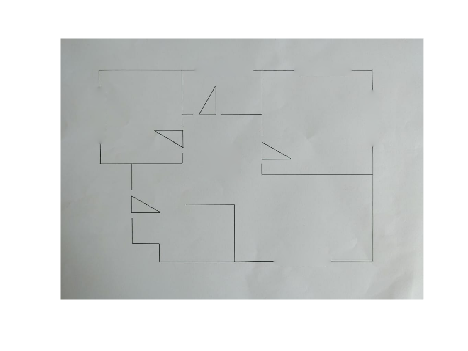

imshow(ImgWthNoWindows);

## Contour Detection Using CORF (3rd Time)

% --- Convert to grayscale ---
gray = ImgWthNoWindows;

gray = im2double(gray);

% --- Optional smoothing ---
gray = imgaussfilt(gray, 1.0);   % sigma ≈ 1 for mild smoothing

% --- Apply CORF contour detector ---
[img_height, img_width] = size(gray);
img_diagonal = sqrt(img_height^2 + img_width^2);

% Scale sigma based on image size
% For close-up: sigma = 2.5 works
% For full page: sigma should be proportionally smaller
base_diagonal = 1000;  % Adjust based on your close-up image size
sigma = 2.5 * (base_diagonal / img_diagonal);
sigma = max(1.0, min(sigma, 3.0));  % Clamp between 1.0 and 3.0

t = 0.3;  

[~, bin] = CORF(gray, sigma, t); % bin is a binary contour image
bin_filled = imfill(bin, 'holes');
bin_filled = imclose(bin_filled, strel('disk', 5));
[B, ~] = bwboundaries(bin_filled, 'noholes');

## Triangle Detection

% Detect triangles
triangles = detectTriangles(B, size(ImgWthNoWindows));
% Enclose triangle in bounding box
[ImgWthOnlyLines, DoorBboxes] = blurOutTriangles(ImgWthNoWindows, triangles, scale);

Filling region 1: [451:512, 193:298]
Filling region 2: [259:321, 261:367]
Filling region 3: [127:228, 394:457]
Filling region 4: [296:355, 573:677]


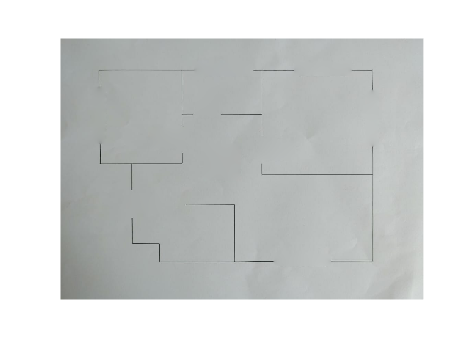

imshow(ImgWthOnlyLines);

## Line Segment Detection

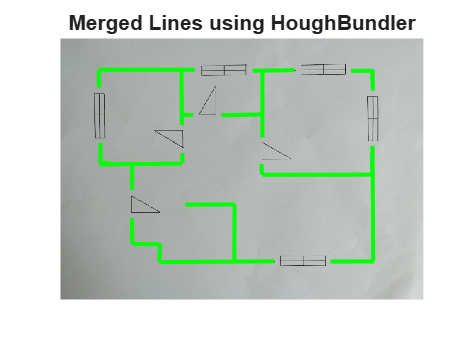

ImgWthOnlyLinesGray = rgb2gray(ImgWthOnlyLines);
%--- Run LSD Algorithm by Rafael ---
% LSD function can be tuned to improve performance
[line_segments, ~, ~] = lsd(ImgWthOnlyLinesGray, 'scale', 1.0, 'ang_th', 22.5, 'log_eps', 3.0, 'density_th', 0.85);

% Extract line segment coordinates
line_coordinates = line_segments(:, 1:4);

% An average of 25 000 - 30 000 line segments can be detected so
% merging could take some time computationally
min_distance = 10;
min_angle = 5;
WallLines = merge_groups(line_coordinates, min_distance, min_angle);
size(WallLines);

figure
imshow(NoBackgroundImage);
hold on;
title('Merged Lines using HoughBundler');
for i = 1:size(WallLines,1)
    x = [WallLines(i,1) WallLines(i,3)];
    y = [WallLines(i,2) WallLines(i,4)];
    plot(x, y, 'g-', 'LineWidth', 2);
end
hold off;

## Window Feature Extraction

OriginalImg = NoBackgroundImage;
%gap_max = 50.0;  % Maximum allowable distance to be considered a neighbor

%window_marker = [];
%all_window_lines = [];

% Scale all window boxes by 10 %
scalew = 0.1;
scaled_windowBoxes = bboxScaler(WindowBboxes, scalew);
WindowBboxes = scaled_windowBoxes;

% Preallocate with zeros before the loop
window_marker = zeros(size(WindowBboxes, 1), 4);

for i = 1:size(WindowBboxes, 1) % Loop over all window boxes
    bbox = WindowBboxes(i,:);
    cropped_img = cropImage(OriginalImg, bbox, scalew);
    [pot_window_lines] = detectAndFilterLines(cropped_img, bbox, scalew);
    window_lines = filterSixWindowLines(pot_window_lines);
    %all_window_lines = [all_window_lines;window_lines;[0 0 0 0]]; % for
    marker = WindowPlacementMarker9(window_lines, WallLines);
    % Store the window marker and filtered lines for further processing
    window_marker(i,:) = marker;

end

## Visualize Window Placement positions

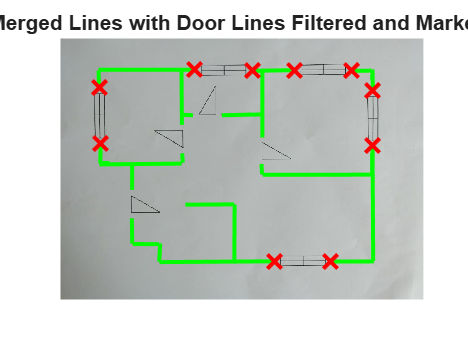

% --- Display Result ---
imshow(OriginalImg);
hold on;
title('Merged Lines with Door Lines Filtered and Markers');
for i = 1:size(WallLines, 1)
    x = [WallLines(i,1) WallLines(i,3)];
    y = [WallLines(i,2) WallLines(i,4)];
    plot(x, y, 'g-', 'LineWidth', 2);
end
for i = 1:size(window_marker, 1)
    if window_marker(i,1) ~= 0 && window_marker(i,2) ~= 0
        plot(window_marker(i,1), window_marker(i,2), 'rx', 'MarkerSize', 10, 'LineWidth', 2);
    end
    if window_marker(i,3) ~= 0 && window_marker(i,4) ~= 0
        plot(window_marker(i,3), window_marker(i,4), 'rx', 'MarkerSize', 10, 'LineWidth', 2);
    end
end
hold off

## Door Feauture Extraction

%door_markers = [];
%all_door_lines = [];
%all_door_lines1 = [];
scale = 0.1;
scaled_doorBoxes = bboxScaler(DoorBboxes, scale);
DoorBboxes = scaled_doorBoxes;

% Preallocate with zeros before the loop
door_markers = zeros(size(DoorBboxes, 1), 4);

for i = 1:size(DoorBboxes, 1)
    bbox = DoorBboxes(i, :);
    cropped_img = cropImage(OriginalImg, bbox, scale);
    pot_door_lines = detectAndFilterLines(cropped_img, bbox, scalew);
    door_lines = filterTriangleLines(pot_door_lines);
    %all_door_lines = [all_door_lines; door_lines; [0 0 0 0]];
    
    if ~isempty(door_lines)
        lineLengths = sqrt((door_lines(:,3) - door_lines(:,1)).^2 + (door_lines(:,4) - door_lines(:,2)).^2);
        [~, minIndex] = min(lineLengths);
        shortestLine = door_lines(minIndex, :);
        marker = doorPlacementMarker(shortestLine, WallLines, 10.0, 50.0);
        if any(marker)
            door_markers(i,:) = marker;
        end
    end
end
mask = ~(door_markers(:,1)==0 & door_markers(:,2)==0); % keep rows not both zero
door_markers = door_markers(mask,:);

## Visualize Door Placement Positions

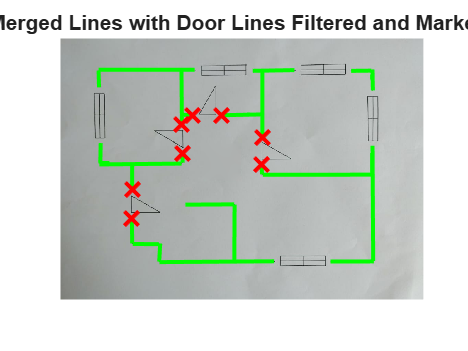

% --- Display Result ---
imshow(OriginalImg);
hold on;
title('Merged Lines with Door Lines Filtered and Markers');
for i = 1:size(WallLines, 1)
    x = [WallLines(i,1) WallLines(i,3)];
    y = [WallLines(i,2) WallLines(i,4)];
    plot(x, y, 'g-', 'LineWidth', 2);
end
for i = 1:size(door_markers, 1)
    if door_markers(i,1) ~= 0 && door_markers(i,2) ~= 0
        plot(door_markers(i,1), door_markers(i,2), 'rx', 'MarkerSize', 10, 'LineWidth', 2);
    end
    if door_markers(i,3) ~= 0 && door_markers(i,4) ~= 0
        plot(door_markers(i,3), door_markers(i,4), 'rx', 'MarkerSize', 10, 'LineWidth', 2);
    end
end
hold off

## Translate All Results From Cropped Image Coordinates To Actual Image Coordinates

% ---Step 1: List Out Items To Translate ---
% - door_markers: Precise door placement coordinates
% - WallLines: wall lines
% - window_marker: Precise window placement coordinates

% ---Step 2: Commence Translation using cropBox---
wall_lines_orig = translateCropCoorToOriginal(WallLines, cropBox);
door_markers_orig = translateCropCoorToOriginal(door_markers, cropBox);
window_markers_orig = translateCropCoorToOriginal(window_marker, cropBox);


## Virtual 3D Visual of Building

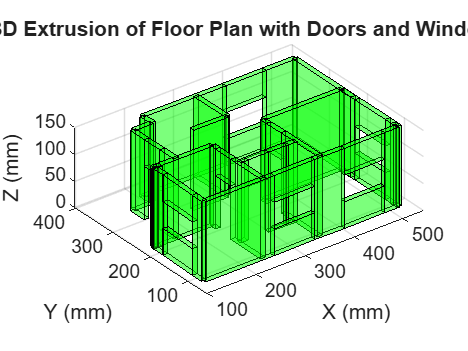

% --- Parameters ---
wallHeight = 150;        % mm
wallThickness = 10;      % mm
scaleFactor = 0.5;      % mm per pixel (adjust as needed)
% Heights for doors/windows
doorBase = (2/3)*wallHeight;
%doorTop = wallHeight;
windowLowerHeight = (1/3)*wallHeight;
windowUpperBase = (2/3)*wallHeight;

% --- Scaled coordinates ---
scaleLines = @(L) L * scaleFactor;
lines = scaleLines(wall_lines_orig);
doors = scaleLines(door_markers_orig);
windows = scaleLines(window_markers_orig);

% --- Initialize storage ---
%allVertices = [];
%allFaces = [];
faceOffset = 0;

% Preallocate with zeros before the loop
allVertices = zeros(size(lines, 1)*8, 3);
allFaces = zeros(size(lines, 1)*6, 4);


% --- Extrude Walls Fully ---
for i = 1:size(lines, 1)
    line = lines(i, :);
    vertices = createCuboidFromLine(line, wallHeight, wallThickness);

    % Add vertices and faces
    %allVertices = [allVertices; vertices];
    vStart = (i - 1) * 8 + 1;
    vEnd   = i * 8;
    allVertices(vStart:vEnd, :) = vertices;

    faces = [1 2 3 4; 5 6 7 8; 1 5 6 2; 2 6 7 3; 3 7 8 4; 4 8 5 1] + faceOffset;
    
    fStart = (i - 1) * 6 + 1;
    fEnd   = i * 6;
    allFaces(fStart:fEnd, :) = faces;
    %allFaces = [allFaces; faces];
    faceOffset = faceOffset + 8;
end

% --- Doors: Upper 1/3 wall ---

currentVCount = size(allVertices, 1);
currentFCount = size(allFaces, 1);
allVertices(currentVCount + (size(doors, 1) * 8), 3) = 0;
allFaces(currentFCount + (size(doors, 1) * 6), 4) = 0;

for i = 1:size(doors, 1)
    door = doors(i, :);
    vertices = createCuboidFromLineAtHeight(door, doorBase, wallHeight - doorBase, wallThickness);

    %allVertices = [allVertices; vertices];
    vStart = currentVCount + (i - 1) * 8 + 1;
    vEnd   = currentVCount + i * 8;
    allVertices(vStart:vEnd, :) = vertices;

    faces = [1 2 3 4; 5 6 7 8; 1 5 6 2; 2 6 7 3; 3 7 8 4; 4 8 5 1] + faceOffset;
    %allFaces = [allFaces; faces];
    fStart = currentFCount + (i - 1) * 6 + 1;
    fEnd   = currentFCount + i * 6;
    allFaces(fStart:fEnd, :) = faces;

    faceOffset = faceOffset + 8;
end

% --- Windows: Lower 1/3 ---

currentVCount = size(allVertices, 1);
currentFCount = size(allFaces, 1);
allVertices(currentVCount + (size(windows, 1) * 8), 3) = 0;
allFaces(currentFCount + (size(windows, 1) * 6), 4) = 0;
for i = 1:size(windows, 1)
    window = windows(i, :);
    vertices = createCuboidFromLineAtHeight(window, 0, windowLowerHeight, wallThickness);

    %allVertices = [allVertices; vertices];
    vStart = currentVCount + (i - 1) * 8 + 1;
    vEnd   = currentVCount + i * 8;
    allVertices(vStart:vEnd, :) = vertices;

    faces = [1 2 3 4; 5 6 7 8; 1 5 6 2; 2 6 7 3; 3 7 8 4; 4 8 5 1] + faceOffset;
    
    %allFaces = [allFaces; faces];
    fStart = currentFCount + (i - 1) * 6 + 1;
    fEnd   = currentFCount + i * 6;
    allFaces(fStart:fEnd, :) = faces;

    faceOffset = faceOffset + 8;
end

% --- Windows: Upper 1/3 ---

currentVCount = size(allVertices, 1);
currentFCount = size(allFaces, 1);
allVertices(currentVCount + (size(windows, 1) * 8), 3) = 0;
allFaces(currentFCount + (size(windows, 1) * 6), 4) = 0;
for i = 1:size(windows, 1)
    window = windows(i, :);
    vertices = createCuboidFromLineAtHeight(window, windowUpperBase, windowLowerHeight, wallThickness);

    %allVertices = [allVertices; vertices];
    vStart = currentVCount + (i - 1) * 8 + 1;
    vEnd   = currentVCount + i * 8;
    allVertices(vStart:vEnd, :) = vertices;

    faces = [1 2 3 4; 5 6 7 8; 1 5 6 2; 2 6 7 3; 3 7 8 4; 4 8 5 1] + faceOffset;
    %allFaces = [allFaces; faces];
    fStart = currentFCount + (i - 1) * 6 + 1;
    fEnd   = currentFCount + i * 6;
    allFaces(fStart:fEnd, :) = faces;

    faceOffset = faceOffset + 8;
end

% --- Visualization ---
figure;
patch('Vertices', allVertices, 'Faces', allFaces, ...
      'FaceColor', 'g', 'FaceAlpha', 0.3, 'EdgeColor', 'k');
axis equal;
xlabel('X (mm)'); ylabel('Y (mm)'); zlabel('Z (mm)');
title('3D Extrusion of Floor Plan with Doors and Windows');
view(3); grid on;

## Convert 2D Pixel Coordinates To Real World Coordinates

camExtrinsics = tagPose;
%--- Step 1: Convert wall lines from image Coordinates To World ----
% Initialize wall_lines_world
numLines = size(wall_lines_orig, 1);
wall_lines_world = zeros(numLines, 4);

% Loop over each wall line
for i = 1:numLines
    % Extract current line's endpoints as a 2x2 matrix
    line_2d = [wall_lines_orig(i,1:2); wall_lines_orig(i,3:4)];  % [x1 y1; x2 y2]
    
    % Initialize lines variable for this pair
    lines = zeros(2, 2);
    
    for j = 1:2
        imagePoint = line_2d(j, :);  % 1x2 point [x y]
        
        % Convert image point to world coordinates
        lines(j, :) = img2world2d(imagePoint, camExtrinsics, intrinsics);
    end
    
    % Flatten [x1 y1; x2 y2] -> [x1 y1 x2 y2]
    wall_lines_world(i, :) = reshape(lines.', 1, []);  % Transpose + reshape
end

%--- Step 2: Convert door marker positions from image to world
%coordinates ---

numLines = size(door_markers_orig, 1);
door_markers_world = zeros(numLines, 4);

% Loop over each door marker
for i = 1:numLines
    % Extract current line's endpoints as a 2x2 matrix
    line_2d = [door_markers_orig(i,1:2); door_markers_orig(i,3:4)];  % [x1 y1; x2 y2]
    
    % Initialize lines variable for this pair
    lines = zeros(2, 2);
    
    for j = 1:2
        imagePoint = line_2d(j, :);  % 1x2 point [x y]
        
        % Convert image point to world coordinates
        lines(j, :) = img2world2d(imagePoint, camExtrinsics, intrinsics);
    end
    
    % Flatten [x1 y1; x2 y2] -> [x1 y1 x2 y2]
    door_markers_world(i, :) = reshape(lines.', 1, []);  % Transpose + reshape
end

%--- Step 3: Convert window marker positions from image to world
%coordinates ---

numLines = size(window_markers_orig, 1);
window_markers_world = zeros(numLines, 4);

% Loop over each window marker
for i = 1:numLines
    % Extract current line's endpoints as a 2x2 matrix
    line_2d = [window_markers_orig(i,1:2); window_markers_orig(i,3:4)];  % [x1 y1; x2 y2]
    
    % Initialize lines variable for this pair
    lines = zeros(2, 2);
    
    for j = 1:2
        imagePoint = line_2d(j, :);  % 1x2 point [x y]
        
        % Convert image point to world coordinates
        lines(j, :) = img2world2d(imagePoint, camExtrinsics, intrinsics);
    end
    
    % Flatten [x1 y1; x2 y2] -> [x1 y1 x2 y2]
    window_markers_world(i, :) = reshape(lines.', 1, []);  % Transpose + reshape
end


## Test On Reference Image

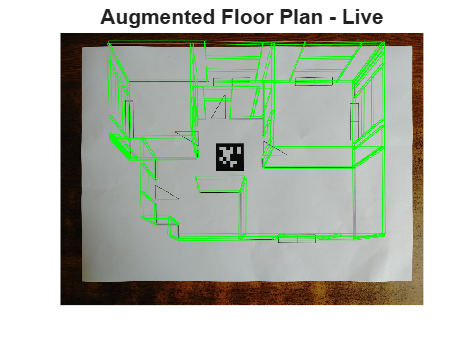

%load("calibrationSession.mat");  % should contain 'cameraParams'

wallHeight = 50;      % mm
wallThickness = 2;    % mm

figure;
% --- Detect AprilTag and get pose ---

[~, ~, tagPose] = readAprilTag(img_ref, tagFamily, intrinsics, tagSize);

% Rotate Z axis if needed
rotationAngles = [0 180 0];
tform = rigidtform3d(rotationAngles, [0 0 0]);
updatedR = tagPose.R * tform.R;
tagPose = rigidtform3d(updatedR, tagPose.Translation);

% --- Project floor plan into image ---
augmentedImage = projectExtrudedPlan(img_ref, wall_lines_world, door_markers_world, window_markers_world, intrinsics, tagPose, wallHeight, wallThickness);

% --- Display ---
imshow(augmentedImage);
title('Augmented Floor Plan - Live');

drawnow;